addpath brainwaves
addpath lidar
addpath color_masking
addpath utils

moj = get_mojave();

moj.setup();

Setup complete


moj.lidar.lidar_setup();

lidar_fig = figure("Name", "Lidar", "NumberTitle", "off", "Visible","on");
ang_fig = figure("Name", "Angular Brainwaves", "NumberTitle", "off", "Visible","on");
vel_fig = figure("Name", "Velocity Brainwaves", "NumberTitle","off", "Visible","on");
ir_fig = figure("Name", "IR Brainwaves", "NumberTitle","off", "Visible","on");

steer_angle = 0;
moj.steer(steer_angle);

% leave_depot(moj);
wave1 = @(m) go_straight(m);
wave2 = @(m) avoid_color(m,@(i) grass_mask(i));
wave3 = @(m) lidar_wave(m);
wave4 = @(m) lidar_inside_brainwave(m, 1500);
wave5 = @(m) follow_color(m,@(i) beige_mask(i));
wave6 = @(m) sonar_brainwave(m);
wave7 = @(m) correction_wave(m);
wave8 = @(m) ir_brainwave(m);
arb_to_slolem = arbiter({wave1 wave3 wave4 wave7}, linspace(0, 1, 13), linspace(-30,30, 13), moj);
run_robot(moj, arb_to_slolem, 1);

Elapsed time is 0.000283 seconds.
Elapsed time is 3.521074 seconds.
Elapsed time is 3.524384 seconds.
Elapsed time is 4.987042 seconds.
Elapsed time is 4.991310 seconds.


Elapsed time is 6.207896 seconds.
Elapsed time is 6.209684 seconds.


Elapsed time is 7.204230 seconds.
Elapsed time is 7.205962 seconds.


Elapsed time is 8.146046 seconds.
Elapsed time is 8.147710 seconds.


Elapsed time is 8.894573 seconds.
Elapsed time is 8.896024 seconds.


Elapsed time is 9.690443 seconds.
Elapsed time is 9.691939 seconds.


Elapsed time is 10.636318 seconds.
Elapsed time is 10.637597 seconds.


Elapsed time is 11.464398 seconds.
Elapsed time is 11.467491 seconds.


Elapsed time is 12.247068 seconds.
Elapsed time is 12.249154 seconds.


moj.lidar.tilt_lidar(5);

Elapsed time is 166.699195 seconds.
Elapsed time is 167.307923 seconds.


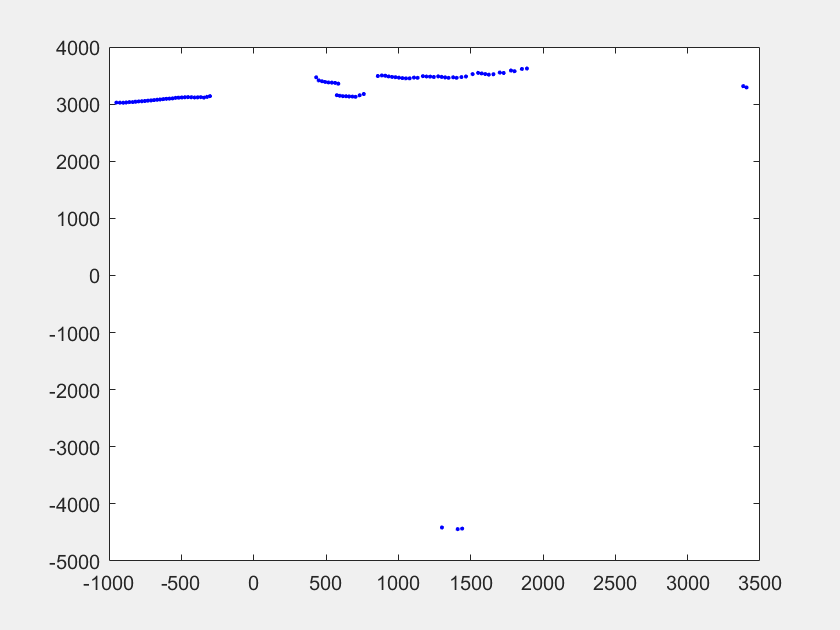

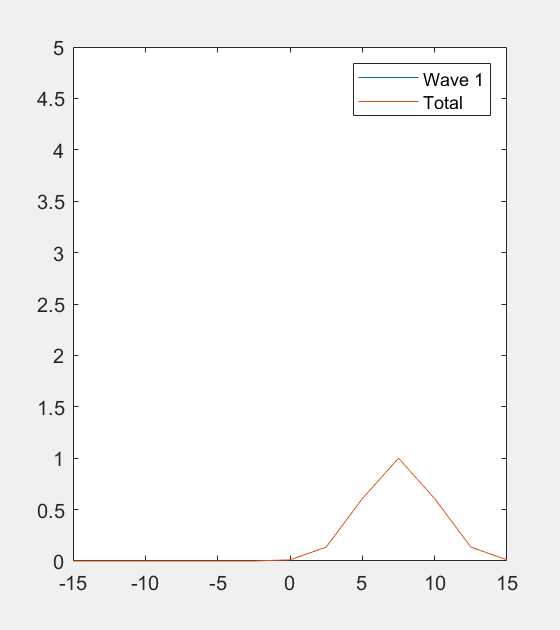

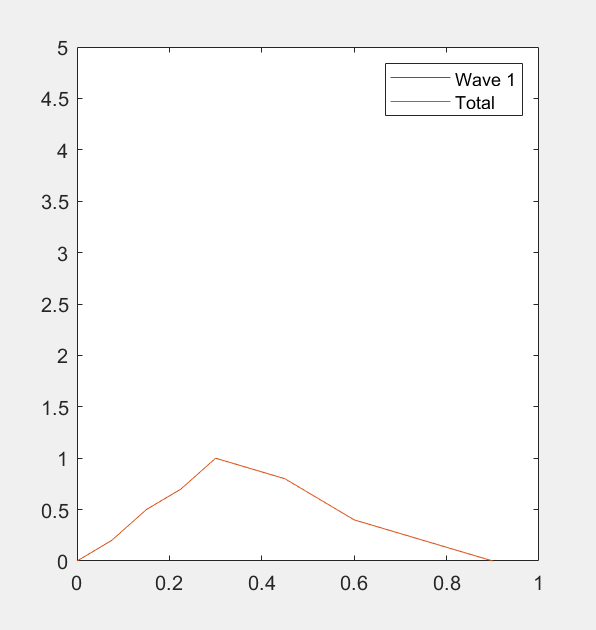

Elapsed time is 167.849696 seconds.


Array indices must be positive integers or logical values.

Error in main>until_tag_seen (line 34)
        ids(i) = tags(i).id;

Error in main (line 28)
run_robot(moj,arb_slolem, @(m) until_tag_seen(m, 4));

Error in 

wave1 = @(m) go_straight(m);
wave2 = @(m) maintain_dist_from_cone(m,@(i) cone_mask(i));
wave3 = @(m) lidar_bridge(m);
wave4 = @(m) lidar_wave(m);
arb_slolem = arbiter({wave4}, linspace(0, .9, 13), linspace(-15,15, 13), moj);
run_robot(moj,arb_slolem, @(m) until_tag_seen(m, 4));

test_arb = arbiter({wave1 wave7}, linspace(0, .9, 13), linspace(-15,15, 13), moj);
test_arb.arbitrate();

Unable to perform assignment because the size of the left side is 1-by-13 and the size of the right side is
0-by-0.

Error in arbiter/get_waves (line 67)
                vel_vec(i, :) = vel;

Error in arbiter/get_wave_sum (line 26)
            [vwaves, awaves] = obj.get_waves();

Error in 

test_arb.get_waves()

moj.lidar.lidar_shutdown();

function done = until_tag_seen(mojave, tag_id)
    tags = mojave.find_april_tags();
    ids = zeros(size(tags));
    for i = length(tags)
        ids(i) = tags(i).id;
    end

    done = false;
    if ~any(ids == tag_id)
        return
    end
    tag = tags(ids == tag_id);
    dist = norm(tag.pose.Translation);
    if dist < 4
        done = true
    end
end